%
% Probabilistic Roadmap and Graph search Algorithm (A*)
%
clc
seed = 123123745;
rng(seed)

## Map

nrows = 1300;
ncols = 1300;

obstacles = false(nrows,ncols);
[x, y] = meshgrid(1:ncols, 1:nrows);

## Obstacles

obstacles (y<50 | y>1250 | x<50 | x>1250) = true;
obstacles (y<650 & y>600 & x<200) = true;
obstacles (y<1000 & y>800 & x<1000 & x>620) = true;
obstacles (y<650 & x>500 & x<550) = true;
obstacles (y<650 & y>600 & x<700 & x>500) = true;
obstacles (y<200 & x>360 & x<550) = true;
obstacles (y>1000 & x>550 & x<600) = true;
obstacles (y<1000 & y>950 & x<600 & x>400) = true;
obstacles (y<450 & y>400 & x>1000) = true;



figure;
imshow(~obstacles);

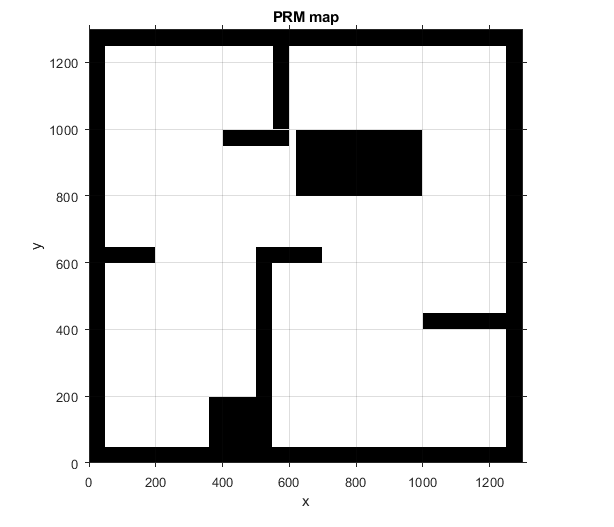


axis ([0 ncols 0 nrows]);
axis xy;
axis on;
xlabel('x');
ylabel('y');

title('PRM map');
grid on

## Probabilistic Roadmap Parameters

Max_node_to_connect = 5;
Max_connect_length = 350;
Segments = 10;
Max_nodes_to_generate = 500;

## Probabilistic Roadmap Algorithm

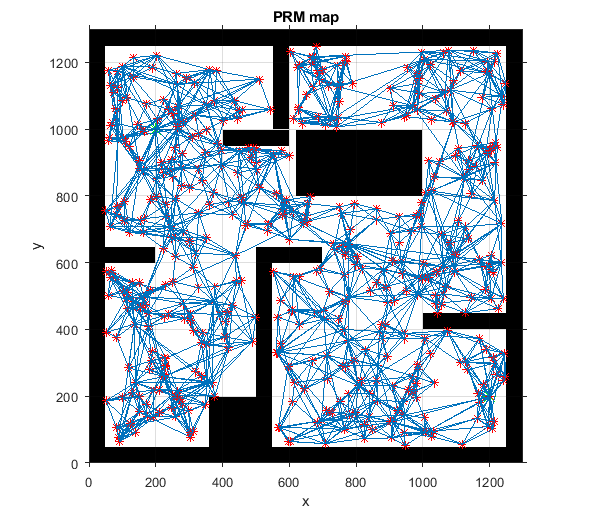

Nodes = 0;
map = zeros(size(obstacles));
map(obstacles) = 1;
Graph_connections = Inf(Max_nodes_to_generate,Max_node_to_connect + 1); %Adjacency Matrix


%Specify the start and goal points
start = [1000,200];
goal = [200,1200];
while (Nodes < Max_nodes_to_generate)
    if (Nodes == 0)
        Node_X = start(2);
        Node_Y = start(1);
    elseif (Nodes == 1)
        Node_X = goal(2);
        Node_Y = goal(1);
    else
        Node_X = randi(ncols); %Randomly generate nodes
        Node_Y = randi(nrows);
    end
    
    
    if (map(Node_Y,Node_X) == 1 || map(Node_Y,Node_X) == 2)
        continue;
    end
    
    
    %Identify nodes on the map
    map(Node_Y,Node_X) = 2;
    
    hold on
    if (Nodes == 0 || Nodes == 1)
        plot(Node_X,Node_Y,'g*','MarkerSize',10);
    else
        plot(Node_X,Node_Y,'r*');
    end
    hold off
    
    Nodes = Nodes + 1;

## Connect to new nodes to the closest Max_node_to_connect nodes within the range Max_connect_length

    nodes_to_connect = [];
    distance = [];
    for i = 1:numel(Graph_connections(:,1))
        if (Graph_connections(i,1) == Inf)
            break;
        end

        [row,col] = ind2sub(size(map),Graph_connections(i,1));

        if(norm([Node_Y,Node_X]-[row,col]) > Max_connect_length)
            continue;
        end

        if(via_obstacle(map,Segments,[Node_Y,Node_X],[row,col]))
            continue;
        end

        nodes_to_connect = [nodes_to_connect,Graph_connections(i,1)];
        distance = [distance;[Graph_connections(i,1),norm([Node_Y,Node_X]-[row,col])]];

    end

## Choose the closest Max_node_to_connect nodes to connect to

    Graph_connections(Nodes,1) = sub2ind(size(map),Node_Y,Node_X);

    if(size(distance > 0))
        distances_sorted = sortrows(distance,2);
        for i = 1:min(Max_node_to_connect,size(distances_sorted,1))
            Graph_connections(Nodes,i+1) = distances_sorted(i,1);

            [row,col] = ind2sub(size(map),distances_sorted(i,1));

            hold on
            line([Node_X,col],[Node_Y,row]) %line(x,y,'Color','red')
            hold off
        end
    end
end

## A* Algorithm

%%Heuristic values
hvalues = [1,numel(Graph_connections(:,1))];
for i = 1:numel(Graph_connections(:,1))
    [row,col] = ind2sub(size(map),Graph_connections(i,1));
    hvalues(i) = norm([row,col] - goal);
end

%Graph
graph = Inf(Max_nodes_to_generate,Max_nodes_to_generate);
indnum = [Max_nodes_to_generate,2];
for i = 1:numel(Graph_connections(:,1))
    indnum(i,1) = i;
    indnum(i,2) = Graph_connections(i,1);
end

for i = 1:numel(Graph_connections(:,1))
    element = Graph_connections(i,1);
    [r,c] = ind2sub(size(map),element);
    for j = 2:Max_node_to_connect + 1
        if (Graph_connections(i,j) ~= inf)
            for z = 1:numel(indnum(:,2))
                if (indnum(z,2) == Graph_connections(i,j))
                    ind = indnum(z,1);
                end
            end
            [nr,nc] = ind2sub(size(map),Graph_connections(i,j));
            graph(i,ind) = norm([r,c] - [nr,nc]);
            graph(ind,i) = norm([r,c] - [nr,nc]);
        end
    end
end

path = AStarSearch(graph,hvalues,Max_nodes_to_generate,indnum)

Shortest path


path =      1   117   141   245    48    65    94    87   122   288    84   118   283   155     2


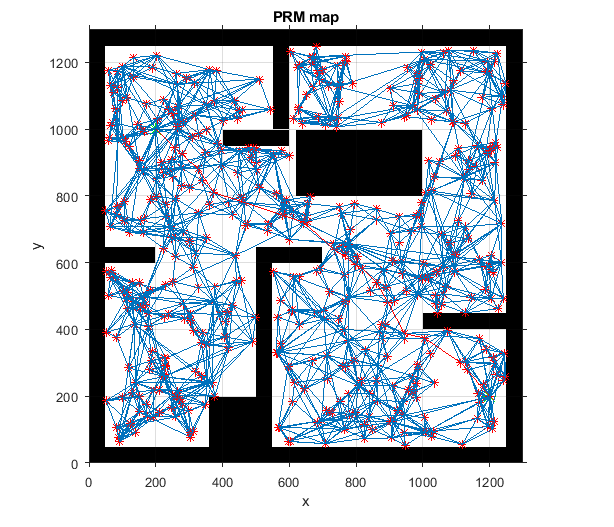



% Draw shortest path
pn = 0;
[prow,pcol] = ind2sub(size(map),indnum(path(1),2));
while pn < numel(path)
    pn = pn + 1;
    [crow,ccol] = ind2sub(size(map),indnum(path(pn),2));
    hold on
    line([pcol,ccol],[prow,crow],'Color','red') 
    hold off
    [prow,pcol] = ind2sub(size(map),indnum(path(pn),2));
end

function path = AStarSearch(graph,hvalues,numNodes,indnum)
    GCost = Inf(1,numNodes);  % Node path cost starting from the start node
    FCost = Inf(1,numNodes);  % F-costs starting from the start node
    Pred = Inf(1,numNodes);   % Node predecessors
    OPEN=[];   % Nodes to open
    CLOSED=[]; % Nodes that are currently explored
    
    % start = indnum(1,1) and goal = indnum(2,1)
    GCost(indnum(1,1)) = 0;
    FCost(indnum(1,1)) = hvalues(indnum(1,1));
    OPEN(1,1) = indnum(1,1);
    OPEN(1,2) = FCost(indnum(1,1));
    
    TermCheck=0;

    if (numel(CLOSED) ~= 0)
        y=numel(CLOSED(:,1)) + 1;
    else
        y=1;
    end
    while ~TermCheck 
        [OPEN_EXTRACTED,OPEN_SORTED] = update_open(OPEN);
        OPEN = OPEN_SORTED;
        
        if OPEN_EXTRACTED(1) == indnum(2,1)
            success = 1;
            break
        else
            successorNodes = [];
            for s = 1:numel(graph(1,:))
                if (graph(OPEN_EXTRACTED(1),s) ~= inf)
                    successorNodes(end+1) = s;%graph(OPEN_EXTRACTED(1),s);
                end
            end
            
            listOpen = [];
            for i = 1:numel(OPEN(:,1))
                listOpen(i) = OPEN(i,1);
            end
            listClose = [];
            if (numel(CLOSED) ~= 0)
                for i = 1:numel(CLOSED(:,1))
                listClose(i) = CLOSED(i,1);
                end
            end
            z=numel(OPEN(:,1))+1;
            for i = successorNodes(1,:)
                pathCost = GCost(OPEN_EXTRACTED(1)) + graph(OPEN_EXTRACTED(1),i);
                cost = pathCost + hvalues(i);
                if cost < FCost(i)
                    if (FCost(i) == inf)
                        GCost(i) = pathCost;
                        FCost(i) = cost;
                        Pred(i) = OPEN_EXTRACTED(1);
                        OPEN(z,:) = [i,cost];
                    elseif (ismember(i, listOpen))
                        nodeIndex = find(listOpen==i);
                        if (OPEN(nodeIndex,2) >= cost)
                            OPEN(nodeIndex,:) = [];
                            GCost(i) = pathCost;
                            FCost(i) = cost;
                            Pred(i) = OPEN_EXTRACTED(1);
                            OPEN(z,:) = [i,cost];
                        end
                    elseif (ismember(i, listClose))
                        nodeIndex = find(listOpen==i);
                        if (CLOSED(nodeIndex,2) > cost)
                            CLOSED(nodeIndex,:) = [];
                            GCost(i) = pathCost;
                            FCost(i) = cost;
                            Pred(i) = OPEN_EXTRACTED(1);
                            OPEN(z,:) = [i,cost];
                        end
                    end
                    z = z+1;
                end
            end
            
        end
        CLOSED(y,:) = [OPEN_EXTRACTED(1),FCost(OPEN_EXTRACTED(1))];
        y=y+1;
        if (numel(OPEN) == 0)
            success = -1;
            TermCheck=1;
        end
    end
    if(success == 1)
        start = indnum(1,1);
        goal = indnum(2,1);
        gcost = GCost;
        fcost = FCost;
        pred = Pred;
        disp('Shortest path');
        path = optimumPath(start,goal,Pred);
    else
        disp('Search is terminated unsuccessfuly');
        disp('Check if your graph is connected');
    end
end


function path = optimumPath(start,goal,Pred)
    p = 1;
    optPath(p) = goal;
    currentNode = goal;
    while currentNode  ~= start
        p = p + 1;
        predNode = Pred(currentNode);
        optPath(p) = predNode;
        currentNode  = predNode;
    end
    path = fliplr(optPath);
end